# Magnetic Levitation Modelling

Bill Fan, Declan Freeman-Gleason

## Plant modelling

### Magnetostatics

We model the electromagnet as a number of close, stacked rings with an iron core. We assume constant current and use Biot-Savart to find the magnetic flux density along the axis of a ring:

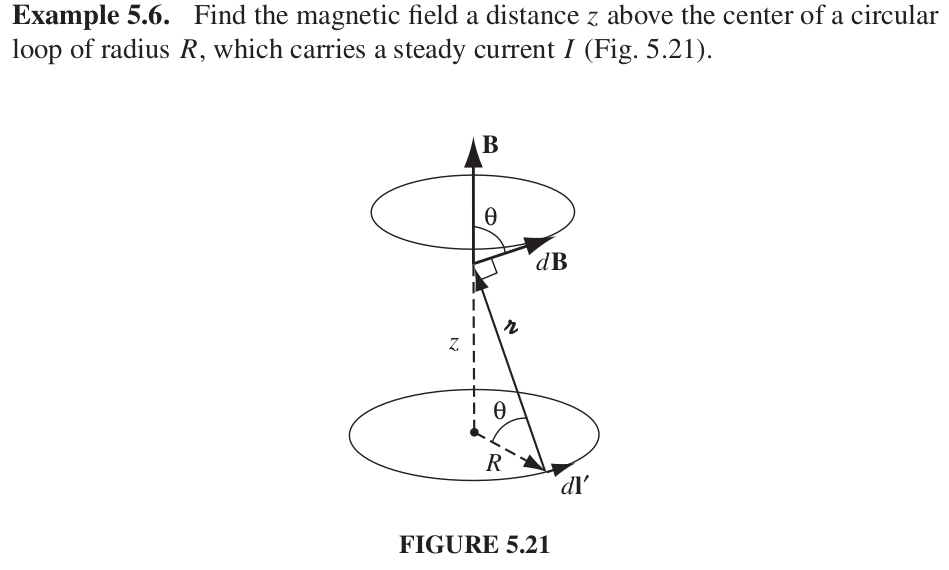

(*Introduction to Electrodynamics* 4th ed., Griffiths)

We did this by hand but the math will be elided for brevity. We can send pictures of the hand derivations if you want.

Then, we extend this to multiple closely (actually infintesimally) stacked rings that we assume approximate a solenoid:

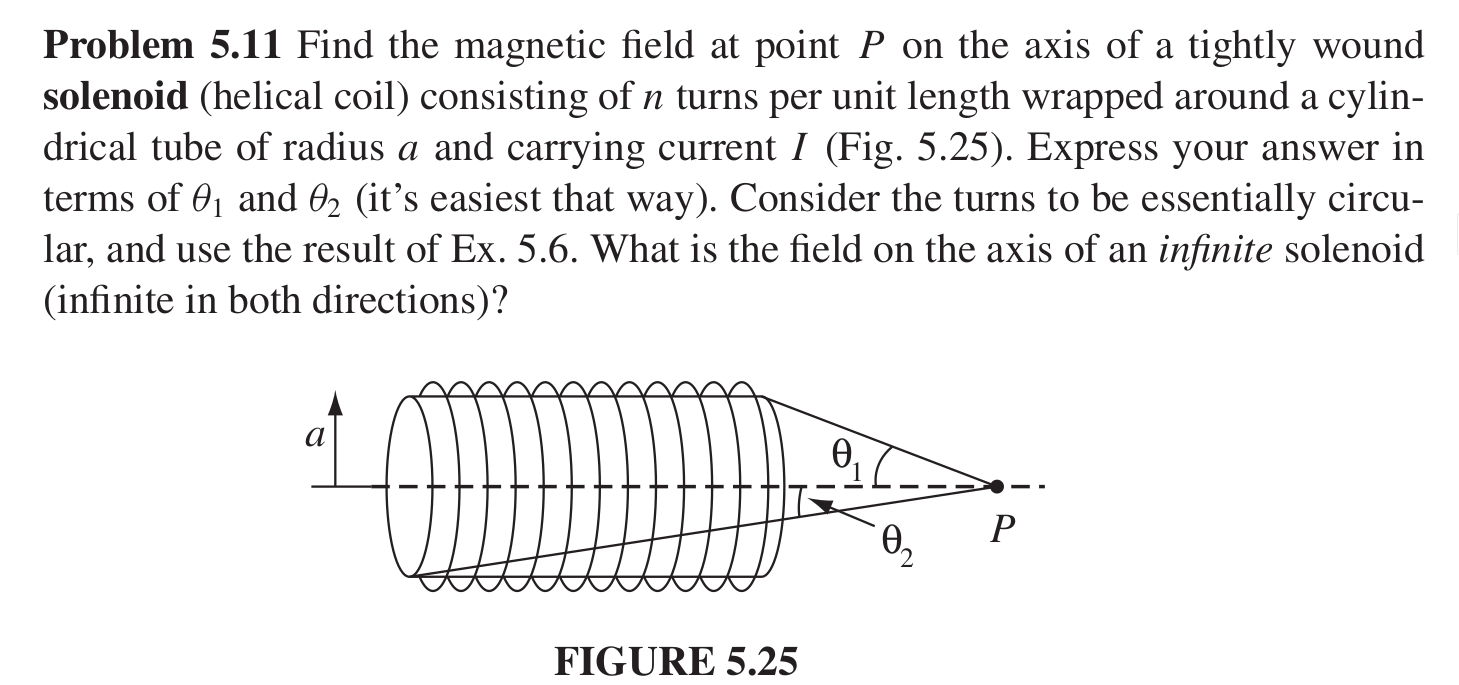

(*Introduction to Electrodynamics* 4th ed., Griffiths)

This requires evaluating the following integral:


$$\mathbf{B}(d) = \frac{\mu_0}{2}\frac{n}{l} I \int_{d}^{d+l}\frac{r^2}{(r^2 + z^2)^{3/2}} \hat \mathbf{k} dz$$


We also changed the permeability of free space to the permeability of a permanent magnet core material so that the above equation applies for an electromagnet. We think this step is questionable and will look into fixing it.

We have also evaluated the above by hand (it's a fun exercise), but we'll use MATLAB® Symbolic™ so we don't have to copy down the math™.

syms mu_iron I n l z r theta_1 theta_2 % Electromagnet parameters
syms mu_0 p l_mag % Magnet parameters

assume([mu_0 I n l z r p l_mag theta_1 theta_2], 'real')
assumeAlso([z r], 'positive')
struct_params = struct();
struct_params.mu_0 = 1.2e-6; % m kg / (s^2 A^2)
struct_params.mu_iron = 6.3e-3; % m kg /(s^2 A^2)
struct_params.n = 50; % # of turns
struct_params.r = 0.01; % Radius (m)
struct_params.p = 48; % Pole strength (amp-meters)
struct_params.l_mag = 0.05; % Length of magnet (m)
struct_params.l = 0.02; % Length of inductor (m)
struct_params.z_bar = 0.04;
struct_params.I_bar = 0.02;

% Magnetic field of a 'solenoid' with an iron core
B = (mu_iron/2)*I*(n/l) * int(r^2/((r^2+z^2)^1.5), z, z, z+l)

$$B = -\frac{\text{I}\,\mu_{\mathrm{iron}}\,n\,\left(\frac{z}{\sqrt{r^{2}+z^{2}}}-\frac{l+z}{\sqrt{{\left(l+z\right)}^{2}+r^{2}}}\right)}{2\,l}$$

$\mu$ is the permeability; $z$ is the distance of  the magnet from the end of the electromagnet core ($z \hat k$ is $P$ in the above diagram); $r$ is the radius of the solenoid; $l$ is the length of the solenoid; $n$ is  the number of windings; finally, $I$ is the current through the windings.

Finally, we used $F = \nabla(\mathbf{m} \cdot \mathbf{B})$ (see Griffiths 4rd ed. page 268; assumes our permenent magnet is an infentesimal current loop) to solve for the force on a magnetic dipole with a magnetic dipole moment $\mathbf{m}$ by a magnetic flux density $\mathbf{B}$:

force = p*l_mag*simplify(diff(B, z))

$$force = \begin{array}{l} \frac{\text{I}\,l_{\mathrm{mag}}\,\mu_{\mathrm{iron}}\,n\,p\,\left(\frac{1}{\sqrt{\sigma_{1}}}-\frac{1}{\sqrt{r^{2}+z^{2}}}+\frac{z^{2}}{{\left(r^{2}+z^{2}\right)}^{3/2}}-\frac{\left(2\,l+2\,z\right)\,\left(l+z\right)}{2\,{\sigma_{1}}^{3/2}}\right)}{2\,l}\\ \mathrm{where}\\ \sigma_{1}={\left(l+z\right)}^{2}+r^{2} \end{array}$$

We currently assume that $\mathbf{m}$ (the dipole moment) is parallel with the axis of the solenoid, so there's no torque on the magnet. We could easily extend the above *and* calculate the torque for when the magnet is rotated about its center, but we don't think this is worthwhile because the Hall effect sensor can't differentiate between rotations and translations.

We have force on the permanent magnet by the electromagnet. We add this to the gravitational force on the magnet: $\sum_{ext} = F_{mag}(z(t), i(t)) + mg = m \ddot z(t)$. Our states are therefore $\mathbf{x} = \left[\matrix{\dot z \cr z}\right]$.

### Linearization and simplification

Because $F_{mag}(z(t))$ contains another function of $t$, $i(t)$, the current through the electromagnent windings, we need to do a multivariate first-order Taylor series expansion to linearize our equation for the force on the magnet, which is nonlinear. This gives us:


$$F_{mag}(z(t), i(t)) \approx F_{mag}(z_{ref}, i_{ref}) + \frac{\partial F_{mag}(z_{ref}, i_{ref})}{\partial z(t)} (z(t) - z_{ref}) + \frac{\partial F_{mag}(z_{ref}, i_{ref})}{\partial i(t)} (i(t) - i_{ref})$$


syms I_bar z_bar % Linearization point
assume([I_bar z_bar], 'real')

% Multivariable taylor series:
% linearize f(x, y) about a,b = f(a, b) + f_x(a, b)(x-a) + f_y(a, b)(y-b)
f_eval = @(sym_exp) (subs(sym_exp, [I, z], [I_bar, z_bar]));
lin_force = f_eval(force) + f_eval(diff(force, z))*(z-z_bar) + f_eval(diff(force, I))*(I-I_bar);
lin_force = simplify(lin_force);

Therefore our linearized equation of motion is $m \ddot z = mg + F_{mag}(z_{ref}, i_{ref}) + \frac{\partial F_{mag}(z_{ref}, i_{ref})}{\partial z(t)} (z(t) - z_{ref}) + \frac{\partial F_{mag}(z_{ref}, i_{ref})}{\partial i(t)} (i(t) - i_{ref})$.

When you expand the above you can extract/collect the coefficients so that the equation of motion becomes $m\ddot z(t) = mg + Az(t) + Bi(t) + C$.

% Display linearized force equation
lin_force

$$lin\_force = \begin{array}{l} \frac{l_{\mathrm{mag}}\,\mu_{\mathrm{iron}}\,n\,p\,r^{2}\,\left(\text{I}\,l^{2}\,\sigma_{1}-\text{I}\,{\bar{z}}^{2}\,\sigma_{2}-3\,\bar{I}\,{\bar{z}}^{2}\,\sigma_{2}-\text{I}\,r^{2}\,\sigma_{2}+\text{I}\,r^{2}\,\sigma_{1}+\text{I}\,{\bar{z}}^{2}\,\sigma_{1}+3\,\bar{I}\,{\bar{z}}^{2}\,\sigma_{1}-3\,\bar{I}\,z\,\bar{z}\,\sigma_{1}+3\,\bar{I}\,z\,\bar{z}\,\sigma_{2}-3\,\bar{I}\,l\,z\,\sigma_{1}+2\,\text{I}\,l\,\bar{z}\,\sigma_{1}+3\,\bar{I}\,l\,\bar{z}\,\sigma_{1}\right)}{2\,l\,\sigma_{1}\,\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}={\left(r^{2}+{\bar{z}}^{2}\right)}^{5/2}\\ \sigma_{2}={\left({\left(l+\bar{z}\right)}^{2}+r^{2}\right)}^{5/2} \end{array}$$

% Extract the coefficients for each variable
[cfs, correspondences] = coeffs(lin_force, [z, I]);
cfs'

$$ans = \begin{array}{l} \left(\begin{array}{c} -\frac{l_{\mathrm{mag}}\,n\,p\,r^{2}\,\bar{\mu_{\mathrm{iron}}}\,\left(3\,\bar{I}\,l\,\sigma_{1}-3\,\bar{I}\,\bar{z}\,\sigma_{2}+3\,\bar{I}\,\bar{z}\,\sigma_{1}\right)}{2\,l\,\sigma_{1}\,\sigma_{2}}\\ \frac{l_{\mathrm{mag}}\,n\,p\,r^{2}\,\bar{\mu_{\mathrm{iron}}}\,\left(l^{2}\,\sigma_{1}-{\bar{z}}^{2}\,\sigma_{2}-r^{2}\,\sigma_{2}+r^{2}\,\sigma_{1}+{\bar{z}}^{2}\,\sigma_{1}+2\,l\,\bar{z}\,\sigma_{1}\right)}{2\,l\,\sigma_{1}\,\sigma_{2}}\\ \frac{l_{\mathrm{mag}}\,n\,p\,r^{2}\,\bar{\mu_{\mathrm{iron}}}\,\left(3\,\bar{I}\,{\bar{z}}^{2}\,\sigma_{1}-3\,\bar{I}\,{\bar{z}}^{2}\,\sigma_{2}+3\,\bar{I}\,l\,\bar{z}\,\sigma_{1}\right)}{2\,l\,\sigma_{1}\,\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(r^{2}+{\bar{z}}^{2}\right)}^{5/2}\\ \sigma_{2}={\left({\left(l+\bar{z}\right)}^{2}+r^{2}\right)}^{5/2} \end{array}$$

The coefficients correspond to the coefficients for $z$, $I$, and the constant term respectively. These are our $A, B,$ and $C$.

We now have our magnetic input force as a linear combination of inputs ($i$) and outputs($z$)

### Transfer function

With this linear combination, we can now calculate the laplace transform:


$$ms^2z = Az + Bi + \frac{1}{s}(C + mg)$$


We will model our electromagnet as an inductor and resistor in series, so $V = Ri + iLs$. We can now substitute $i = \frac{V}{R + Ls}$ into the previous equation:


$$ms^2z = Az + B\frac{V}{R+Ls} + \frac{1}{s}(C+mg)$$


Now our job is to solve for a transfer function with disturbances.

syms s m g R L V A B C
assume([m g R L V A B C], "real")
assumeAlso([g, R, L], "positive")
tf_miso = m*s^2*z == A*z + (B*V)/(R + L*s) + (C + m*g)/s;
tf_miso = isolate(tf_miso, z)

$$tf\_miso = z=-\frac{\frac{C+g\,m}{s}+\frac{B\,V}{R+L\,s}}{A-m\,s^{2}}$$

cfs_tf = coeffs(rhs(tf_miso), V)

$$cfs\_tf = \left(\begin{array}{cc} -\frac{C+g\,m}{s\,\left(A-m\,s^{2}\right)} & -\frac{B}{\left(A-m\,s^{2}\right)\,\left(R+L\,s\right)} \end{array}\right)$$

% First coeff is for constants, second is for V
tf_gravity = z == cfs_tf(1)

$$tf\_gravity = z=-\frac{C+g\,m}{s\,\left(A-m\,s^{2}\right)}$$

tf_controlled = z == cfs_tf(2)

$$tf\_controlled = z=-\frac{B}{\left(A-m\,s^{2}\right)\,\left(R+L\,s\right)}$$

We have a multiple input, single output system which we handle by making gravity a 'disturbance', added before the plant in a standard block diagarm. Displayed above are the two separate components which are added together to get the overall transfer function.

## Sensor Modelling

From Jackson's *Classical Electrodynamics*, the magnetic field strength produced at a point $\mathbf{r}$ (with unit vector $\hat \mathbf{r}$) from the center of a magnetic dipole is:


$$\mathbf{B}(\mathbf{r}) = \frac{\mu_0}{4 \pi} \left(\frac{3 \hat \mathbf{r}(\mathbf{m} \cdot \hat \mathbf{r} - \mathbf{m})}{r^3}\right)$$


Let $\mathbf{r} = z \hat \mathbf{k}$.

A Hall effect sensor can be modelled as:


$$V_{\text{H}} = R_{\text{H}} i _{bias} B_{\perp}$$


(*Hall Effect Devices* 2nd ed., R.S. Popovic)

Where $R_{\text{H}}$ is the Hall coefficient (a lumped parameter as far as we're concerned), and $B_{\perp}$ is the magnitude of the magnetic flux density perpindicular to the hall effect sensor (i.e. in the $\hat \mathbf{k}$ direction.) When you evaluate this you end up getting something equivalent to $V_H = \frac{k}{z^3}$, which is equivalent to a lot of simpler models people use.

Let $B_\perp = B_{em}(z(t)) + B_{pm}(i(t))$ and do a first-order Taylor series expansion to linearize.

## Evaluation

We will do a quick evaluation of the force function. The below constants make it so that positive $z$ is away from the magnet.

### Setup

B_particular = subs(B, struct_params);
force_particular = subs(force, struct_params);
lin_force_particular = subs(lin_force, struct_params);
coeffs_particular = eval(subs(cfs, struct_params));

f_B = matlabFunction(B_particular);
f_force = matlabFunction(force_particular);
f_lin_force_particular = matlabFunction(lin_force_particular);

### Constant current, varying position

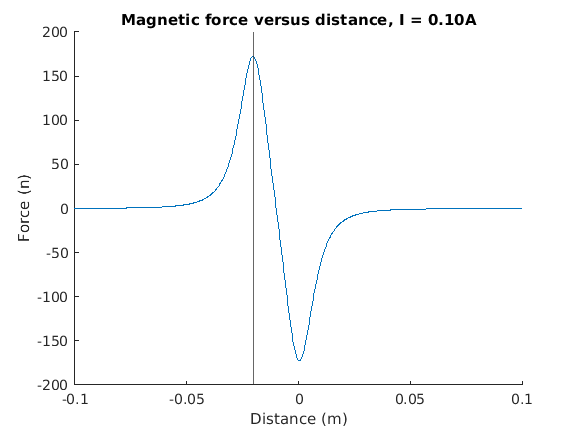

I_val = 0.1; % amps
z_val = linspace(-0.1, 0.1, 1000); % meters
v_force = f_force(I_val, z_val);

figure()
hold on

plot(z_val, v_force);
xline(-struct_params.l);

title(sprintf("Magnetic force versus distance, I = %.2fA", I_val))
xlabel("Distance (m)")
ylabel("Force (n)")

We can see a few things here:

- The force is zero when the magnet is in the center of the coil. Although this isn't phyiscally possible with a solid-core electromagnet, it does demonstrate that our solenoid model is correct: when the magnent is in the center of the solenoid it should have no force applied.

- The force is at its maximum when the center of the magnet is at either end of the solenoid (which corresponds to the peaks; the vertical line is when the magnet's end is at the end of the solenoid.)

- Given our sign conventions above, the force is correctly in the negative direction $z$ is positive. This corresponds to the electromagnet pulling inwards.

- When $z > 0$, our curve is very close to $\frac{1}{r^3}$, which is the usual approximate model for a dipole in a magnetic field.

### Constant position, varying current

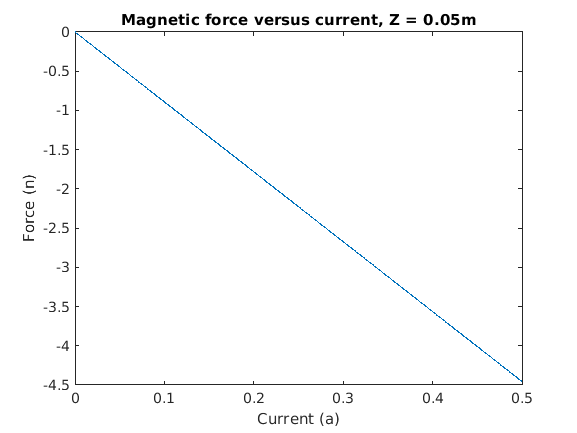

z_val = 0.05; % meters
I_val = linspace(0, 0.5, 1000); % amps
v_force = f_force(I_val, z_val);

figure()
plot(I_val, v_force)
title(sprintf("Magnetic force versus current, Z = %.2fm", z_val))
xlabel("Current (a)")
ylabel("Force (n)")

## References

*Introduction to Electrodynamics* 4th ed., Griffiths

*Classical Electrodynamics* 1st ed., Jackson

*Hall Effect Devices* 2nd ed., R.S. Popovic